# RVC2: Chapter 11 - Image Formation

close all
clear

delete camera object
delete camera object


clc

## 11.1.2  Modelling a perspective camera

cam = CentralCamera('focal', 0.015);

principal point not specified, setting it to centre of image plane



P = [0.3, 0.4, 3.0]';

cam.project(P)

ans =     0.0015
    0.0020


cam.project(P, 'pose', SE3(-0.5, 0, 0) )

ans =     0.0040
    0.0020

## 11.1.3  Discrete image plane

cam = CentralCamera('focal', 0.015, 'pixel', 10e-6, ...
    'resolution', [1280 1024], 'centre', [640 512], 'name', 'mycamera')

delete camera object
cam = 
name: mycamera [central-perspective]                    
  focal length:   0.015                                 
  pixel size:     (1e-05, 1e-05)                        
  principal pt:   (640, 512)                            
  number pixels:  1280 x 1024                           
  T:              t = (0, 0, 0), RPY/zyx = (0, 0, 0) deg



cam.project(P)

ans =    790
   712

## 11.1.4  Camera matrix

cam.K

ans =    1.0e+03 *
    1.5000         0    0.6400
         0    1.5000    0.5120
         0         0    0.0010


cam.C

ans =    1.0e+03 *
    1.5000         0    0.6400         0
         0    1.5000    0.5120         0
         0         0    0.0010         0


cam.fov() * 180/pi

ans =    46.2127   37.6930

## 11.1.5  Projecting points

P = mkgrid(3, 0.2, 'pose', SE3(0, 0, 1.0));

P(:,1:4)

ans =    -0.1000   -0.1000   -0.1000         0
   -0.1000         0    0.1000   -0.1000
    1.0000    1.0000    1.0000    1.0000


cam.project(P)

ans =    490   490   490   640   640   640   790   790   790
   362   512   662   362   512   662   362   512   662

creating new figure for camera


h =   Axes (mycamera) with properties:

             XLim: [0 1280]
             YLim: [0 1024]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties

make axes


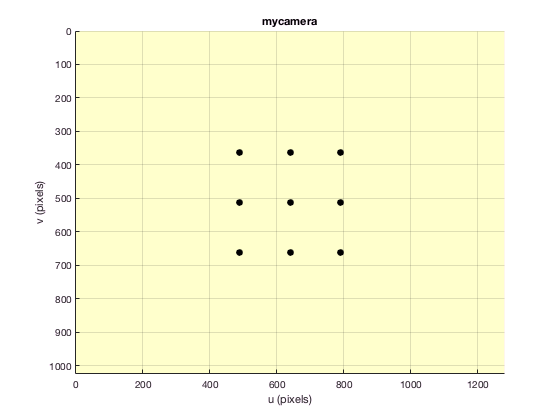


cam.plot(P)

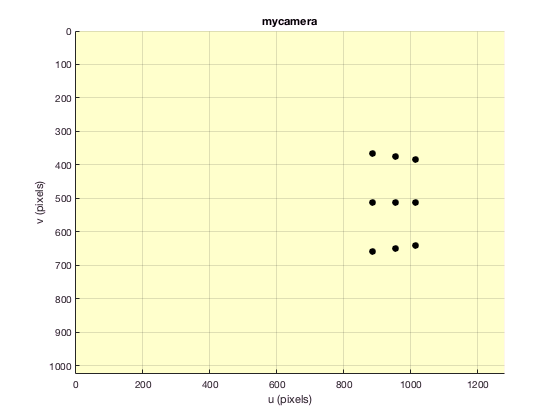


Tcam = SE3(-1,0,0.5)*SE3.Ry(0.9);

cam.plot(P, 'pose', Tcam)


cam.project([1 0 0 0]', 'pose', Tcam)

ans =    1.0e+03 *
    1.8303
    0.5120

p =    1.0e+03 *
    0.8878    0.8878    0.8878    0.9552    0.9552    0.9552    1.0137    1.0137    1.0137
    0.3643    0.5120    0.6597    0.3749    0.5120    0.6491    0.3841    0.5120    0.6399


p = cam.plot(P, 'pose', Tcam)


p(:,1:4)

ans =   887.7638  887.7638  887.7638  955.2451
  364.3330  512.0000  659.6670  374.9050

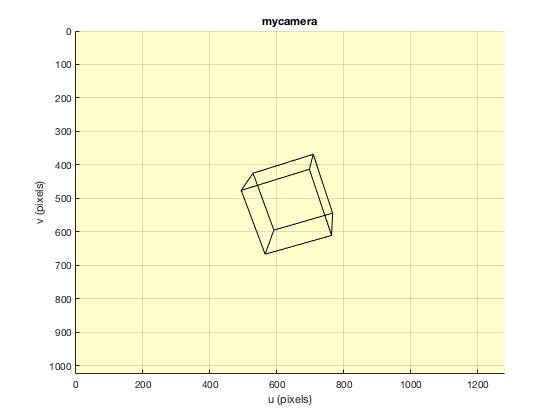


cube = mkcube(0.2, 'pose', SE3(0, 0, 1) );

cam.plot(cube);

[X,Y,Z] = mkcube(0.2, 'pose', SE3(0, 0, 1), 'edge');

cam.mesh(X, Y, Z)

Tcam = SE3(-1, 0, 0.5)*SE3.Ry(0.8);
cam.mesh(X, Y, Z, 'pose', Tcam);

theta = [0:100]/100*2*pi;  % DIFFERENCE make it run for less time than book
[X,Y,Z] = mkcube(0.2, 'edge');
for th=theta
    T_cube = SE3(0,0,1.5)*SE3.rpy(th*[1.1 1.2 1.3]);
    cam.mesh(X, Y, Z, 'objpose', T_cube.T);
    drawnow
end

## 11.1.6  Lens distortion

k1 = 0; k2 = 0; k3 = 0; p1 = 0; p2 = 0;
cam = CentralCamera('focal', 0.015, 'pixel', 10e-6, ...
    'resolution', [1280 1024], 'centre', [512 512], ...
    'distortion', [k1 k2 k3 p1 p2])

delete camera object
cam = 
name: noname [central-perspective]                      
  focal length:   0.015                                 
  distortion:     k=(0, 0, 0), p=(0, 0)                 
  pixel size:     (1e-05, 1e-05)                        
  principal pt:   (512, 512)                            
  number pixels:  1280 x 1024                           
  T:              t = (0, 0, 0), RPY/zyx = (0, 0, 0) deg


## 11.2.1  Homogeneous transformation approach

randinit
P = mkcube(0.2);

T_unknown = SE3(0.1, 0.2, 1.5) * SE3.rpy(0.1, 0.2, 0.3);

cam = CentralCamera('focal', 0.015, ...
    'pixel', 10e-6, 'resolution', [1280 1024], ...
    'noise', 0.05);

principal point not specified, setting it to centre of image plane
delete camera object



p = cam.project(P, 'objpose', T_unknown)

p =   652.8176  594.8766  795.4504  857.7441  692.1651  640.5742  817.6387  872.4925
  596.0774  795.2309  865.6057  661.7254  579.0384  754.5826  815.2312  636.0036


C = camcald(P, p)

maxm residual 0.066733 pixels.


C =   853.0895 -236.9378  634.2785  740.0438
  222.6439  986.6900  295.7327  712.0152
   -0.1304    0.0610    0.6495    1.0000

## 11.2.2  Decomposing the camera calibration matrix

null(C)'

ans =     0.0809   -0.1709   -0.8138    0.5495


h2e(ans)'

ans =     0.1472   -0.3110   -1.4809

T_unknown.inv.t'

ans =     0.1464   -0.3105   -1.4772


est = invcamcal(C)

est = 
name: invcamcal [central-perspective]                                            
  focal length:   1504                                                           
  pixel size:     (1, 0.9985)                                                    
  principal pt:   (646.8, 504.4)                                                 
  T:              t = (0.147, -0.311, -1.48), RPY/zyx = (-1.87, -12.4, -16.4) deg



est.f/est.rho(1)

ans = 1.5040e+03


cam.f/cam.rho(2)

ans = 1.5000e+03


trprint(T_unknown*est.T)

t = (4.13e-05, -4.4e-05, -0.00386), RPY/zyx = (0.296, 0.253, -0.00557) deg


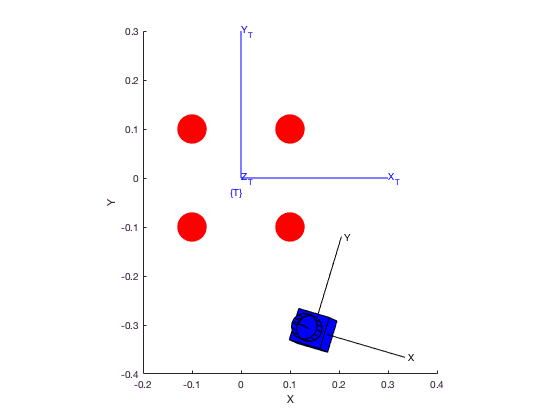


clf
hold on
plot_sphere(P, 0.03, 'r')
trplot(eye(4,4), 'frame', 'T', 'color', 'b', 'length', 0.3)

est.plot_camera()

## 11.2.3  Pose estimation

cam = CentralCamera('focal', 0.015, 'pixel', 10e-6, ...
    'resolution', [1280 1024], 'centre', [640 512]);

P = mkcube(0.2);

T_unknown = SE3(0.1, 0.2, 1.5) * SE3.rpy(0.1, 0.2, 0.3);
T_unknown.print

t = (0.1, 0.2, 1.5), RPY/zyx = (5.73, 11.5, 17.2) deg



p = cam.project(P, 'objpose', T_unknown);

T_est = cam.estpose(P, p).print

T_est = t = (0.1, 0.2, 1.5), RPY/zyx = (5.73, 11.5, 17.2) deg

## 11.2.4  Camera calibration toolbox

%calib_gui

%visualize_distortions

## 11.3.1  Fisheye lens camera

cam = FishEyeCamera('name', 'fisheye', ...
         'projection', 'equiangular', ...
         'pixel', 10e-6, ...
         'resolution', [1280 1024])

principal point not specified, setting it to centre of image plane
delete camera object
cam = 
name: fisheye [FishEye]                                 
  model:          equiangular                           
  k:              0.003259                              
  pixel size:     (1e-05, 1e-05)                        
  principal pt:   (640, 512)                            
  number pixels:  1280 x 1024                           
  T:              t = (0, 0, 0), RPY/zyx = (0, 0, 0) deg


creating new figure for camera


h =   Axes (fisheye) with properties:

             XLim: [0 1280]
             YLim: [0 1024]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties

make axes


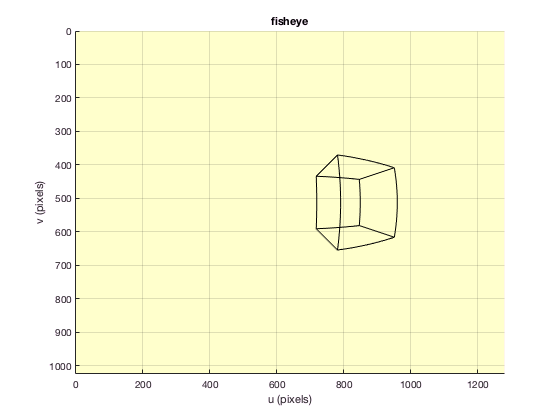

     
[X,Y,Z] = mkcube(0.2, 'centre', [0.2, 0, 0.3], 'edge');

cam.mesh(X, Y, Z)

## 11.3.2  Catadioptric camera

cam = CatadioptricCamera('name', 'panocam', ...
         'projection', 'equiangular', ...
         'maxangle', pi/4, ...
         'pixel', 10e-6, ...
         'resolution', [1280 1024])

principal point not specified, setting it to centre of image plane
delete camera object
cam = 
name: panocam [FishEye]                                 
  model:          equiangular                           
  k:              0.002173                              
  pixel size:     (1e-05, 1e-05)                        
  principal pt:   (640, 512)                            
  number pixels:  1280 x 1024                           
  T:              t = (0, 0, 0), RPY/zyx = (0, 0, 0) deg


creating new figure for camera


h =   Axes (panocam) with properties:

             XLim: [0 1280]
             YLim: [0 1024]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties

make axes


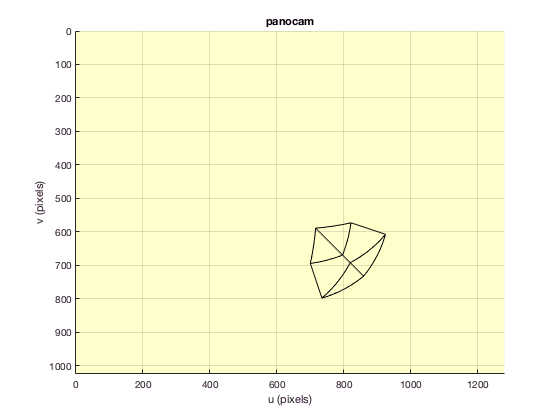

     
[X,Y,Z] = mkcube(1, 'centre', [1, 1, 0.8], 'edge');

cam.mesh(X, Y, Z)

## 11.3.3  Spherical camera

cam = SphericalCamera('name', 'spherical')

principal point not specified, setting it to centre of image plane
delete camera object
cam = 
name: spherical [Spherical]                             
  pixel size:     (1, 1)                                
  T:              t = (0, 0, 0), RPY/zyx = (0, 0, 0) deg


creating new figure for camera


h =   Axes (spherical) with properties:

             XLim: [-3.1416 3.1416]
             YLim: [0 3.1416]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties

make axes


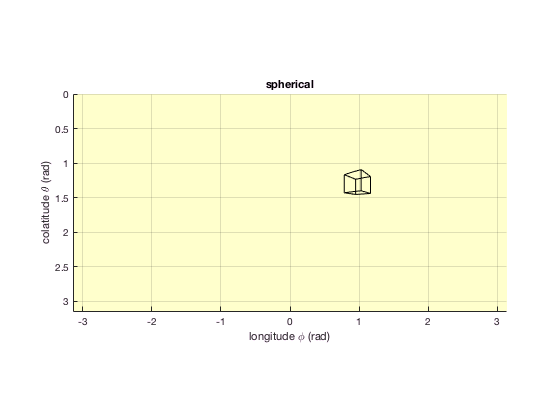


[X,Y,Z] = mkcube(1, 'centre', [2, 3, 1], 'edge');

cam.mesh(X, Y, Z)

## 11.4.1  Mapping wide angle images to the sphere

Set the parameters of the fisheye camera that took the picture, then load the image

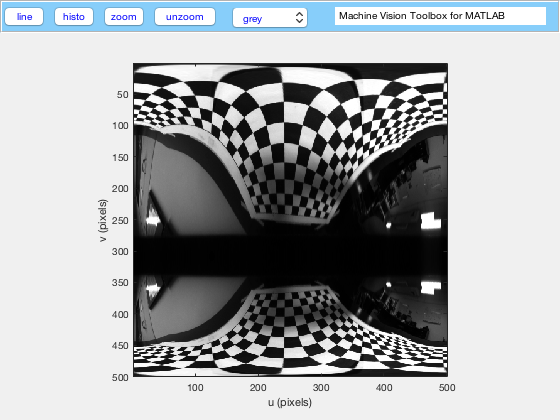

u0 = 528.1214; v0 = 384.0784; l = 2.7899; m = 996.4617;

fisheye = iread('fisheye_target.png', 'double', 'grey');

[Ui,Vi] = imeshgrid(fisheye);

n = 500;
theta_range = linspace(0, pi, n);
phi_range = linspace(-pi, pi, n);
[Phi,Theta] = meshgrid(phi_range, theta_range);

r = (l+m)*sin(Theta) ./ (l-cos(Theta));

U = r.*cos(Phi) + u0;
V = r.*sin(Phi) + v0;

spherical = interp2(Ui, Vi, fisheye, U, V);

idisp(spherical)

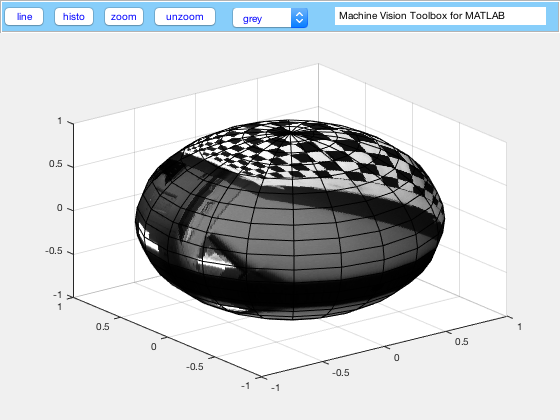


sphere
h = findobj('Type', 'surface');
set(h, 'CData', flipud(spherical), 'FaceColor', 'texture');

colormap(gray)

## 11.4.2  Mapping from the sphere to a perspective image

W = 1000;
m = W / 2 / tan(45/2*pi/180)

m = 1.2071e+03

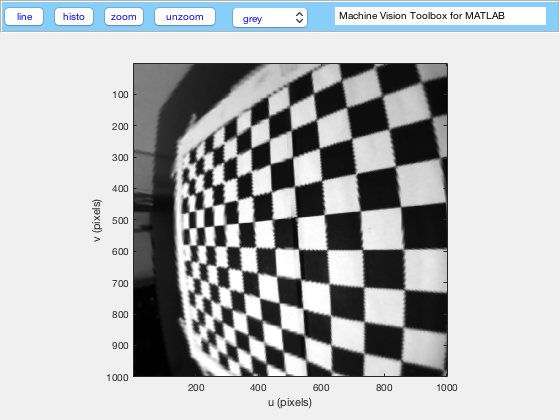


l = 0;

u0 = W/2; v0 = W/2;

[Uo,Vo] = meshgrid(0:W-1, 0:W-1);

[phi,r ]= cart2pol(Uo-u0, Vo-v0);

Phi_o = phi;
Theta_o = pi - atan(r/m);

perspective = interp2(Phi, Theta, spherical, Phi_o, Theta_o);

idisp(perspective)

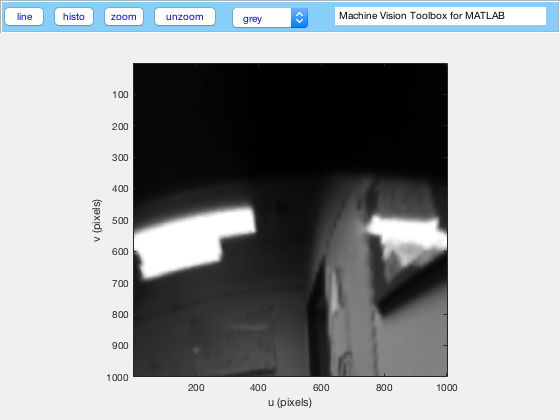


spherical = sphere_rotate(spherical, SE3.Ry(0.9)*SE3.Rz(-1.5));


idisp( interp2(Phi, Theta, spherical, Phi_o, Theta_o) )  % this line not actually in the book, creates Fig 11.26b

## 11.6.1  Projecting 3D lines and quadrics

L = Plucker([0 0 1], [1 1 1])

L = 
{ -1  1  0; -1  -1  0 }



L.w'

ans =     -1    -1     0


cam = CentralCamera('default');

principal point not specified, setting it to centre of image plane
delete camera object


l = cam.project(L)'

l =      1    -1     0

creating new figure for camera


h =   Axes with properties:

             XLim: [0 1024]
             YLim: [0 1024]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties

make axes


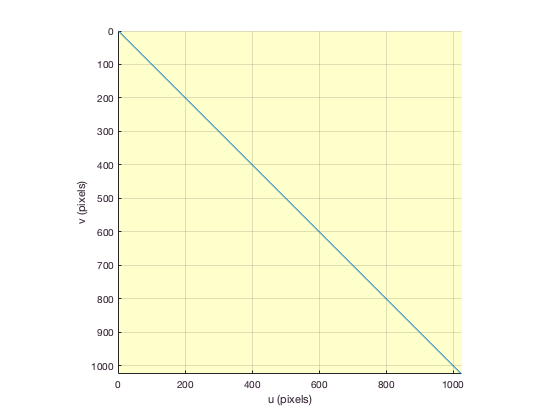


cam.plot(L)

cam = CentralCamera('default', 'pose', SE3(0.2,0.1, -5)*SE3.Rx(0.2));

principal point not specified, setting it to centre of image plane
delete camera object



Q = diag([1 1 1 -1]); 

Qs = inv(Q)*det(Q); % adjugate
cs = cam.C * Qs * cam.C';
c = inv(cs)*det(cs);  % adjugate

det(c(1:2,1:2))

ans = 2.2862e+14

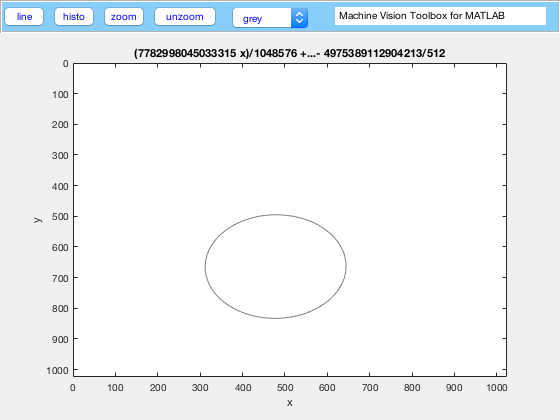


syms x y real
ezplot([x y 1]*c*[ x y 1]', [0 1024 0 1024])
set(gca, 'Ydir', 'reverse')